# Main code to run

clear all; clc;

addpath('core');

%% Numerical parameters
at = 0.5; bt = 0.5; gt = 0.8; as = 0.5; bs = 0.5; gs = 0.5;  

dt = 0.001;    % time-step 
nT = 2000;      % Number of  time-steps
Length = 1;       % has to be defined in 'YG_new_direct' as well
ds = 0.01; % has to be defined in 'F_vec' and 'YG_new_direct' and 'jacobina_Fy' and 'Yprime' as well
N = Length/ds +1; % Number of  space-steps

global E I1 I2 I3 G ro Ac radi m poiss

%% function in space 2s^3−4s^2+3s+1 
%f(s) = 2*(ds*(j-1))^3-4*(ds*(j-1))^2+3*(ds*(j-1))+1;
%f'(s) = 6*(ds*(j-1))^2-8*(ds*(j-1))+3;
%% function in curvature 600k^3+10000k

poiss=0.25;

radi=0.0141/2;
I1=(pi/4)*(radi^4);
Ac=pi*radi^2;
m=9.8;
ro=m/Ac;
I2=I1;
I3=2*I1;

E=10000/I1;
G=E/(2*(1+poiss));

%iteration numbers would appear in increments of 50
Y_time_march = run_numeric(N, ds, dt, nT, as, at, bs, bt, gs, gt);  % run your solver

d = 50

d = 100

d = 150

d = 200

d = 250

d = 300

d = 350

d = 400

d = 450

d = 500

d = 550

d = 600

d = 650

d = 700

d = 750

d = 800

d = 850

d = 900

d = 950

d = 1000

d = 1050

d = 1100

d = 1150

d = 1200

d = 1250

d = 1300

d = 1350

d = 1400

d = 1450

d = 1500

d = 1550

d = 1600

d = 1650

d = 1700

d = 1750

d = 1800

d = 1850

d = 1900

d = 1950

d = 2000

## Save the variables

save('variable_name.mat')

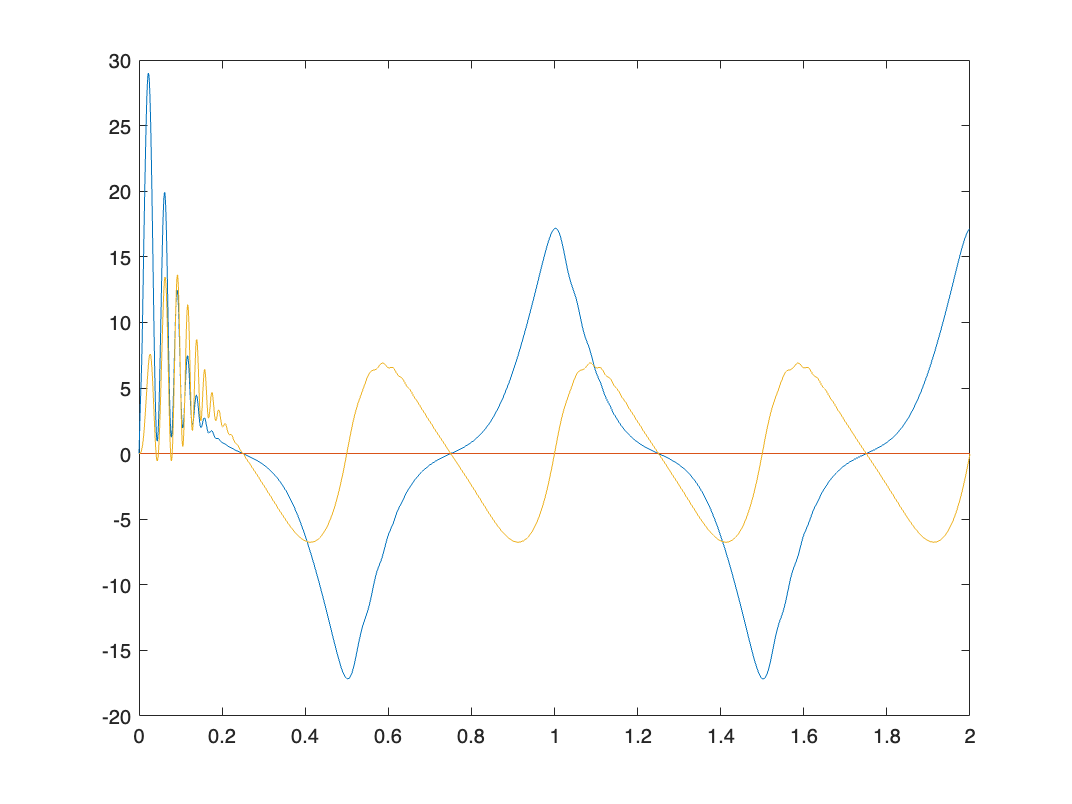

%% Post Processing

nT=length(Y_time_march(1,end,:))-1;
len=0:ds:Length;
time=0:dt:nT*dt;

set(0,'defaultTextInterpreter','latex')
%% Visualize each variable at the free end

% linear velocities (v: 1,2,3)
plot(time,squeeze(Y_time_march(1,end,:)))
hold on
plot(time,squeeze(Y_time_march(2,end,:)))
plot(time,squeeze(Y_time_march(3,end,:)))
hold off

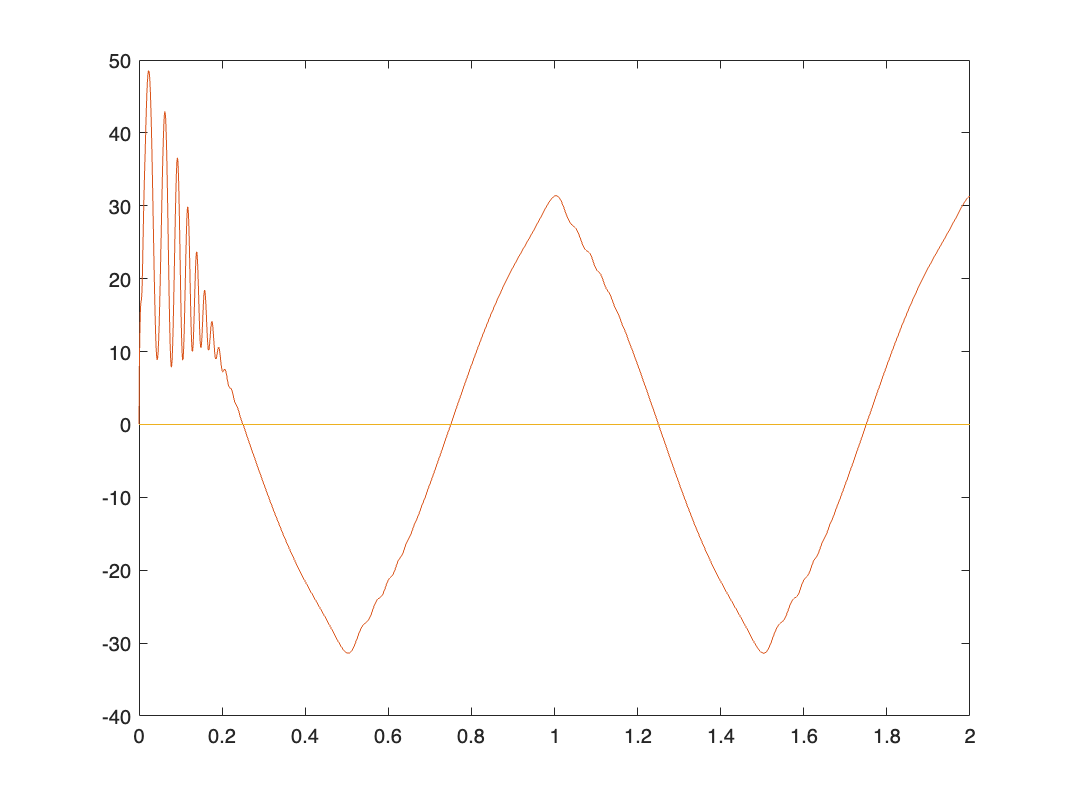


% angular velocities (w: 1,2,3)
plot(time,squeeze(Y_time_march(4,end,:)))
hold on
plot(time,squeeze(Y_time_march(5,end,:)))
plot(time,squeeze(Y_time_march(6,end,:)))
hold off

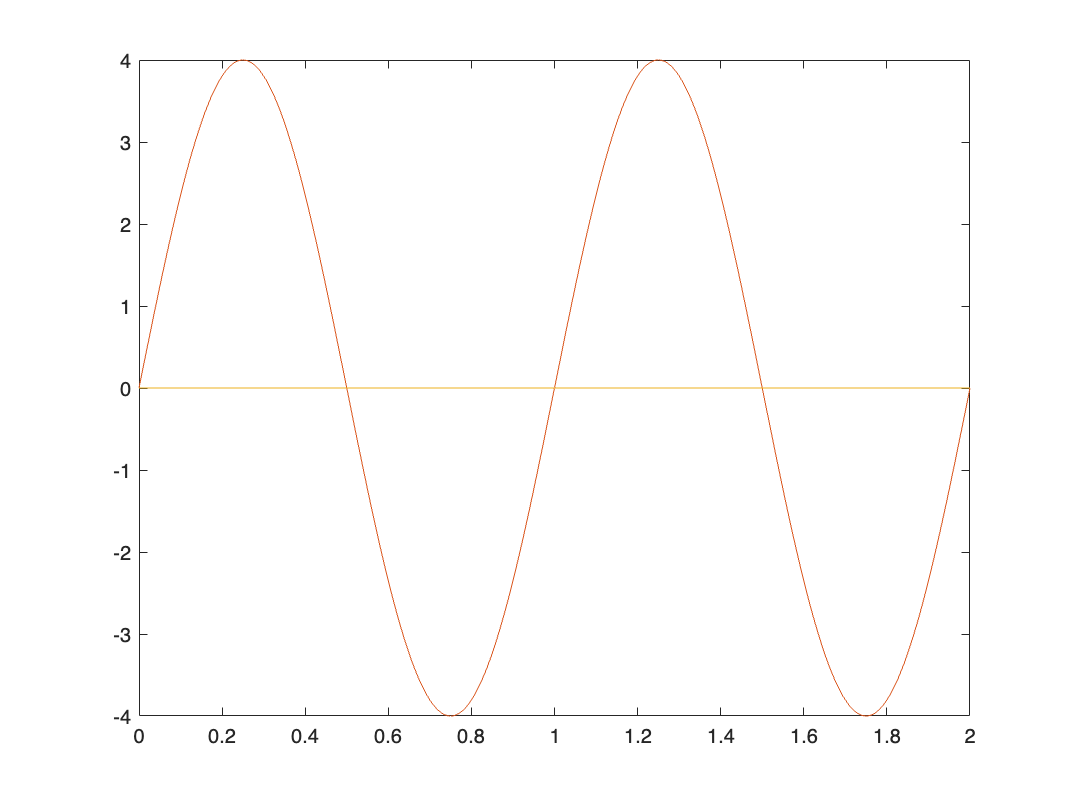


% curvature (k: 1,2,3)
plot(time,squeeze(Y_time_march(7,end,:)))
hold on
plot(time,squeeze(Y_time_march(8,end,:)))
plot(time,squeeze(Y_time_march(9,end,:)))
hold off

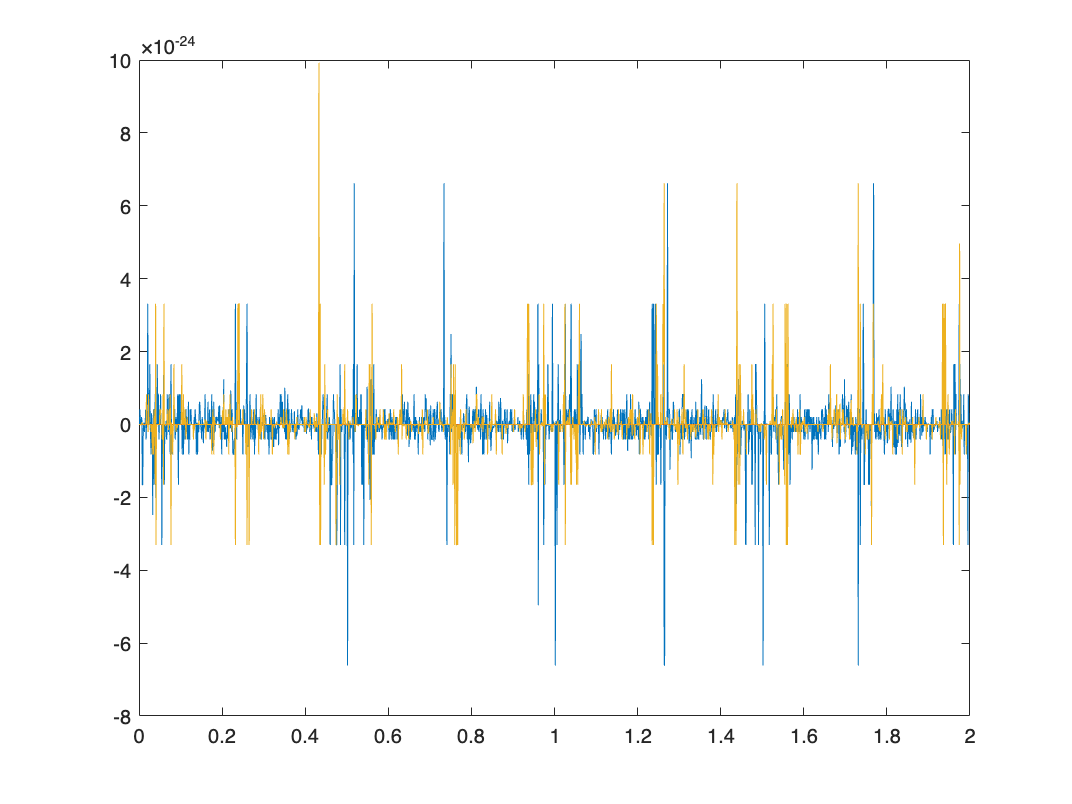


% internal forces (f: 1,2,3)
plot(time,squeeze(Y_time_march(10,end,:)))
hold on
plot(time,squeeze(Y_time_march(11,end,:)))
plot(time,squeeze(Y_time_march(12,end,:)))
hold off

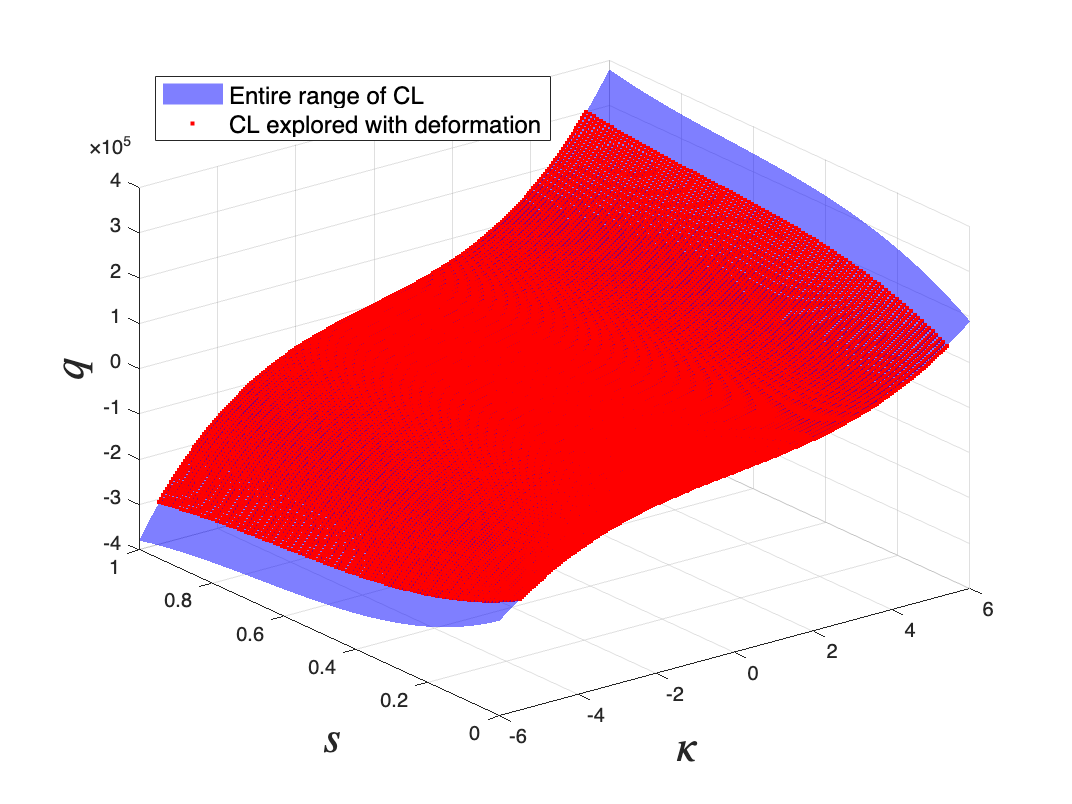


%% View the exact law covered by the deformed shape vs entire range
kappa_range = -6:0.05:6;
kappa_exp = min(min(min(Y_time_march(7:9,:,:)))):0.05:max(max(max(Y_time_march(7:9,:,:))));

for i=1:length(len)
    M_range(i,:)=(2*len(i)^3-4*len(i)^2+3*len(i)+1)*(600*kappa_range.^3+10000*kappa_range);
    M_exp(i,:)=(2*len(i)^3-4*len(i)^2+3*len(i)+1)*(600*kappa_exp.^3+10000*kappa_exp);
end

x = repmat(kappa_exp,[length(len) 1]);
y = M_exp;
z = repmat(len,[length(M_exp) 1])';

surf(kappa_range,len',M_range,'FaceColor',[0 0 1],'FaceAlpha',0.5,'EdgeColor','none')
hold on
plot3(x(:),z(:),y(:),'r','Marker',".","MarkerSize",6,"LineStyle","none")
hold off
legend('Entire range of CL','CL explored with deformation',Location='northwest',fontsize=12);
xlabel('$\kappa$', 'FontSize', 22);
ylabel('$s$', 'FontSize', 22);
zlabel('$q$', 'FontSize', 22);

%view(90,0)

## Create video to visualize

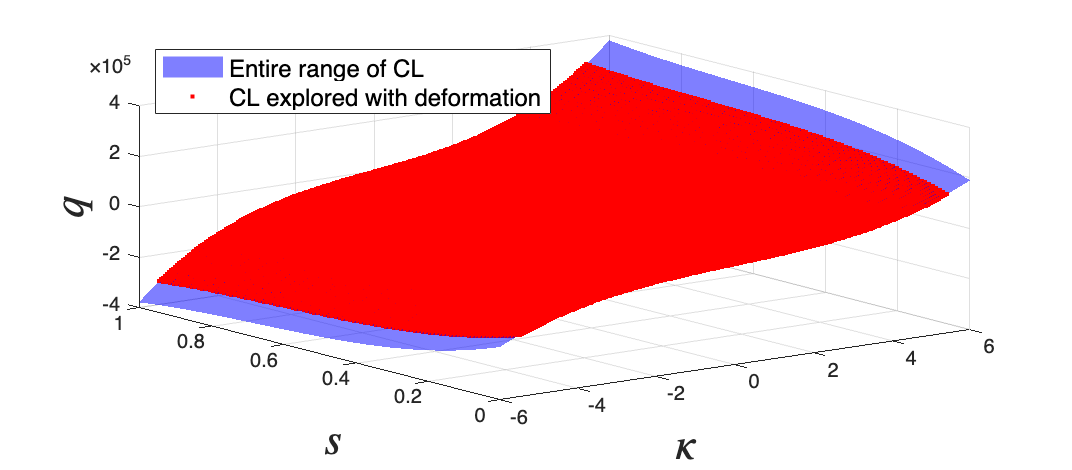

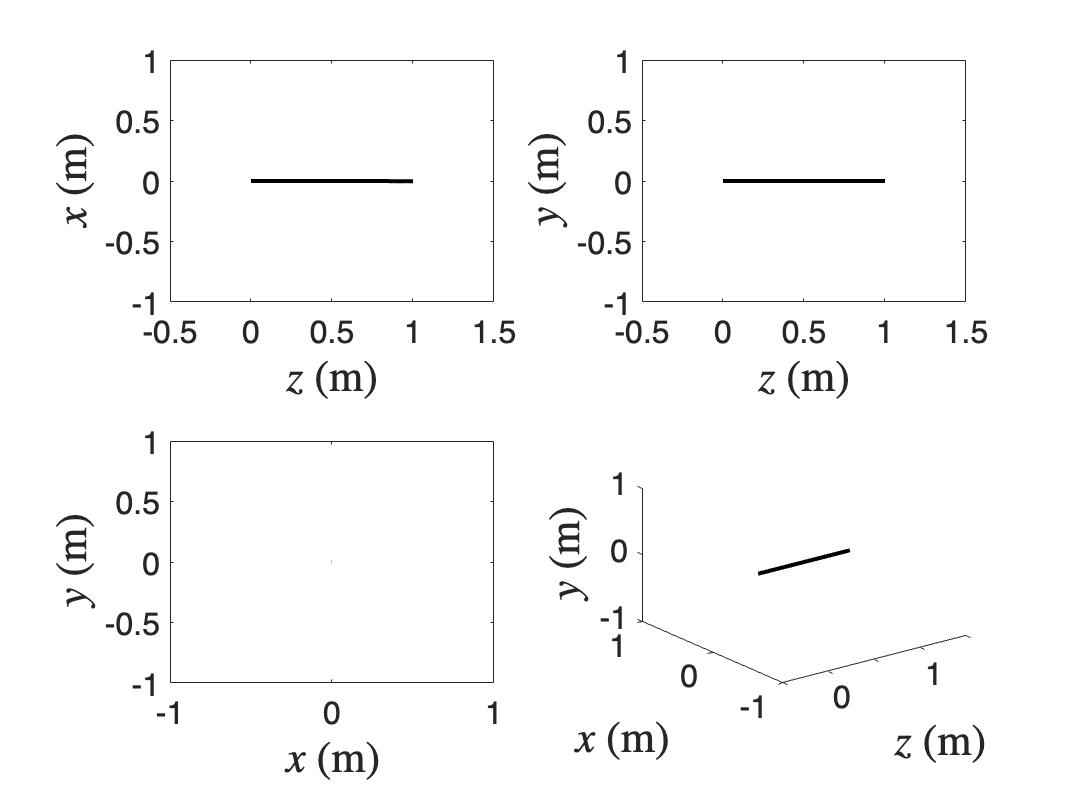

Video saved as video_name.mp4


create_graphic('video_name', Y_time_march, ds);  